# Bird, insect and the rest

**Raphaël Nussbaumer, Baptiste Schmid, Silke Bauer, Felix Liechti**

## **Load the data**

load('data/dc_corr')
load('coastlines.mat')

## Determinde Windspeed at radar location

The U ([parmID=131](https://apps.ecmwf.int/codes/grib/param-db/?id=131)) and V ([parmID=132](https://apps.ecmwf.int/codes/grib/param-db/?id=132)) component of wind are downloaed from the ERA5 reanalysis (ref) at pressure level (from 1000hPa to 550hPa), downloaded at the maximal resoluation (hourly and 0.25°x0.25°). 

See python file

All three variables are linearly interpolated (time-space 4D) at each datapoint of the weather radar data. 

%ncdisp(file{1});
file={'./ECMWF/2018_pressure_1.nc','./ECMWF/2018_pressure_2.nc','./ECMWF/2018_pressure_3.nc','./ECMWF/2018_pressure_4.nc'}; 
wind.time = datenum('01-janv-2018'):1/24:datenum('31-dec-2018 23:00');
wind.latitude=flip(double(ncread(file{1},'latitude')));
wind.longitude=double(ncread(file{1},'longitude'));
wind.pressure=double([ncread(file{1},'level') ; ncread(file{2},'level') ; ncread(file{3},'level') ; ncread(file{4},'level') ]);
wind.alt = (1-(wind.pressure*100/101325).^(1/5.25588))/2.25577/10^(-5);
tmp_1 = permute(flip(ncread(file{1},'u'),2) , [2 1 4 3]); 
tmp_2 = permute(flip(ncread(file{2},'u'),2) , [2 1 4 3]); 
tmp_3 = permute(flip(ncread(file{3},'u'),2) , [2 1 4 3]); 
tmp_4 = permute(flip(ncread(file{4},'u'),2) , [2 1 4 3]); 
wind.u = cat(4,tmp_1,tmp_2,tmp_3,tmp_4); % m/s
tmp_1 = permute(flip(ncread(file{1},'v'),2) , [2 1 4 3]); 
tmp_2 = permute(flip(ncread(file{2},'v'),2) , [2 1 4 3]); 
tmp_3 = permute(flip(ncread(file{3},'v'),2) , [2 1 4 3]); 
tmp_4 = permute(flip(ncread(file{4},'v'),2) , [2 1 4 3]); 
wind.v = cat(4,tmp_1,tmp_2,tmp_3,tmp_4); % m/s
tmp_1 = permute(flip(ncread(file{1},'t'),2) , [2 1 4 3]); 
tmp_2 = permute(flip(ncread(file{2},'t'),2) , [2 1 4 3]); 
tmp_3 = permute(flip(ncread(file{3},'t'),2) , [2 1 4 3]); 
tmp_4 = permute(flip(ncread(file{4},'t'),2) , [2 1 4 3]); 
wind.t = cat(4,tmp_1,tmp_2,tmp_3,tmp_4); % K
clear tmp_* file

Interpolation

Fu = griddedInterpolant({wind.latitude,wind.longitude,datenum(wind.time),wind.alt},wind.u,'linear','linear');
Fv = griddedInterpolant({wind.latitude,wind.longitude,datenum(wind.time),wind.alt},wind.v,'linear','linear');
Ft = griddedInterpolant({wind.latitude,wind.longitude,datenum(wind.time),wind.alt},wind.t,'linear','linear');

for i_d=1:numel(dc)
    windu = permute(Fu({dc(i_d).lat,dc(i_d).lon,datenum(dc(i_d).time),dc(1).alt}),[3,4,1,2]);
    windv = permute(Fv({dc(i_d).lat,dc(i_d).lon,datenum(dc(i_d).time),dc(1).alt}),[3,4,1,2]);
    dc(i_d).wt = permute(Ft({dc(i_d).lat,dc(i_d).lon,datenum(dc(i_d).time),dc(1).alt}),[3,4,1,2]);
    dc(i_d).ws = windu + 1i*windv;
end


clear wind Fu Fv
% save('data/dc_corr','dc','start_date','end_date','quantity','-v7.3')

## Compute airspeed

for i_d=1:numel(dc)

    % Compute the n/s and e/w componenent of the flight speed
    % [-u,v] = pol2cart(deg2rad(dc(i_d).dd+90), dc(i_d).ff);
%     u =  dc(i_d).ff .* sind(dc(i_d).dd); % m/s | 0° is north and 90° is east. -> u is east (+) - west (-)
%     v = dc(i_d).ff .* cosd(dc(i_d).dd); % m/s  -> v is north (+) - south (-)
%     dc(i_d).gs = u + 1i*v;
    dc(i_d).gs =  dc(i_d).ff .* exp(deg2rad(mod(-dc(i_d).dd+90,360))*1i);

    % Remove data not cleaned for density (e.g. rain). 
    id = isnan(dc(i_d).dens3) | dc(i_d).dens3==0;
    dc(i_d).gs(id) = nan;
    dc(i_d).sd_vvp(id) = nan;
    
    dc(i_d).as = dc(i_d).gs - dc(i_d).ws;
end
v_a = reshape(abs([dc(:).as]),numel(dc(1).time), numel(dc(1).alt), numel(dc));
sdvvp = reshape([dc(:).sd_vvp],numel(dc(1).time), numel(dc(1).alt), numel(dc));

Plot airpseed and sdvvp

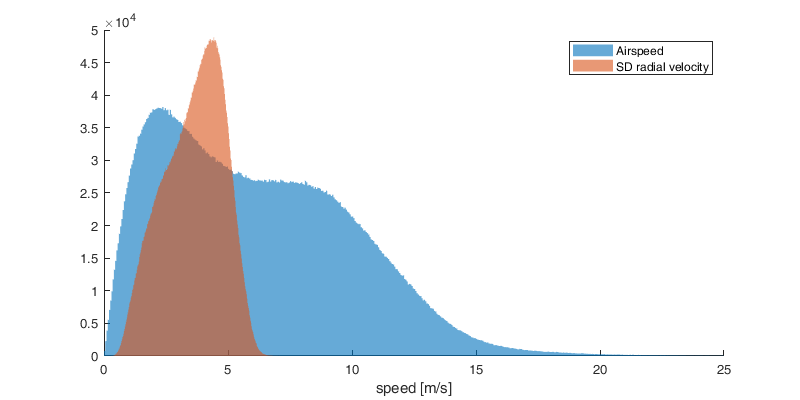

figure('position',[0 0 800 400]); hold on;
histogram(v_a,'EdgeColor','none','DisplayName','Airspeed')
histogram(sdvvp,'EdgeColor','none','DisplayName','SD radial velocity')
legend; xlabel('speed [m/s]'); xlim([0 25])

## Fit the distribution

Build the vector of data removing nan value

X = [v_a(:) sdvvp(:)];
X = X(~any(isnan(X),2),:);

Fit a kernel density function

[xi1, xi2] = meshgrid(0:.25:15,0:.1:7);
ft = reshape(ksdensity(X, [xi1(:), xi2(:)]),size(xi1));
ft = ft./sum(ft(:));

Fit a bi-modal gaussian

gmfit = fitgmdist(X,2,'Replicates',5);

Compute the pdf of each gaussian

gm1 = gmdistribution(gmfit.mu(1,:), gmfit.Sigma(:,:,1));
f_1 = reshape(pdf(gm1,[xi1(:) xi2(:)]),size(xi1));
f_1 = f_1./sum(f_1(:));
gm2 = gmdistribution(gmfit.mu(2,:), gmfit.Sigma(:,:,2));
f_2 = reshape(pdf(gm2,[xi1(:) xi2(:)]),size(xi1));
f_2 = f_2./sum(f_2(:));

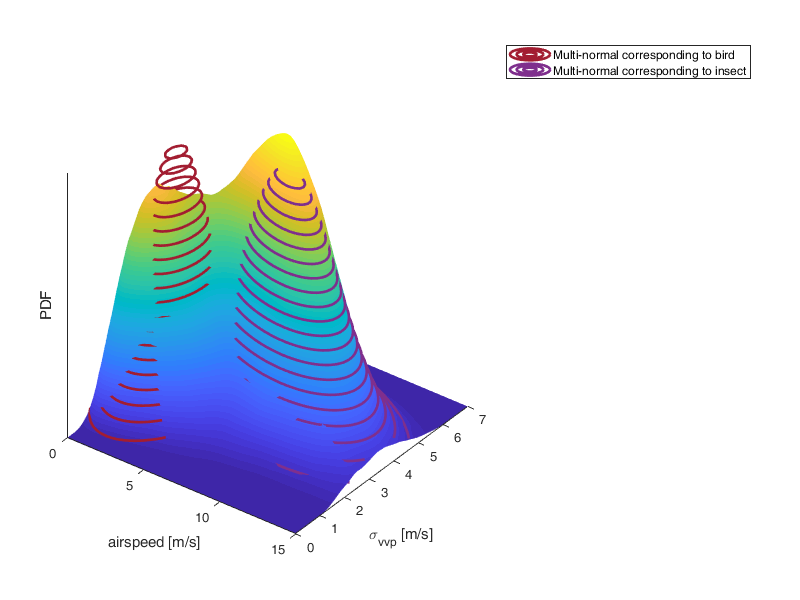

figure('position',[0 0 800 600]); hold on; hold on
% plot(xi1(islocalmax(ft)&islocalmax(ft,2)), xi2(islocalmax(ft)&islocalmax(ft,2)),'.r')
surf(xi1, xi2, ft)
[~,p1]=contour3(xi1, xi2, gmfit.ComponentProportion(1)*f_1,20,'Color',[162 29 49]/255,'linewidth',2);
[~,p2]=contour3(xi1, xi2, gmfit.ComponentProportion(2)*f_2,20,'Color',[127 47 141]/255,'linewidth',2);
axis tight;shading interp; view(37,31)
xlabel('airspeed [m/s]'); ylabel('\sigma_{vvp} [m/s]'); zlabel('PDF')
legend([p1 p2], 'Multi-normal corresponding to bird','Multi-normal corresponding to insect')
Ax = gca; Ax.ZAxis.TickValues=[];

Display parameters

disp(gmfit.mu)

    2.6336    2.7996
    7.9942    4.1045



disp(gmfit.Sigma)


(:,:,1) =

    1.8514    0.1715
    0.1715    1.1029


(:,:,2) =

   11.5021   -1.1682
   -1.1682    0.9156



## Comparison with threashold

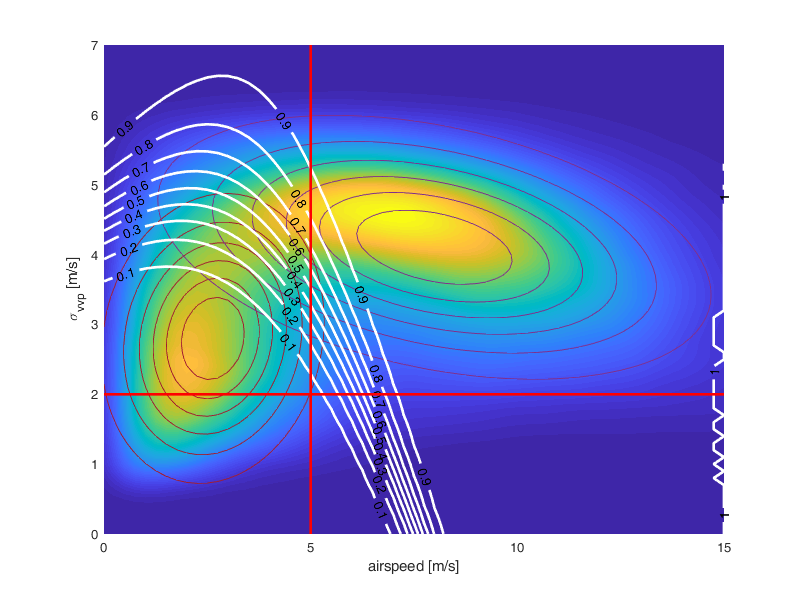

figure('position',[0 0 800 600]); hold on; hold on
pcolor(xi1(1,:), xi2(:,1), ft./max(ft(:)))
contour(xi1, xi2, f_1,6,'Color',[162 29 49]/255);
contour(xi1, xi2, f_2,6,'Color',[127 47 141]/255);
contour(xi1, xi2, f_2./(f_1+f_2),'w','ShowText','on','LineWidth',2)
plot([0 15],[2 2],'r','linewidth',2)
plot([5 5],[0 7],'r','linewidth',2)
axis tight;shading interp;
xlabel('airspeed [m/s]'); ylabel('\sigma_{vvp} [m/s]');

## Over time 

t =  datenum(dc(1).time)-datenum(dc(1).time(1));
batch = 12;
dt = linspace(t(1), t(end), batch+1);

amplit = nan(1,batch);
ftime = nan(size(xi1,1), size(xi1,2),batch);
for i=1:batch
    id = dt(i)<t & dt(i+1)>t;
    X = [reshape(v_a(id,:,:),[],1),reshape(sdvvp(id,:,:),[],1)];
    X = X(~any(isnan(X),2),:);
    if ~isempty(X)
        ftime(:,:,i) = reshape(ksdensity(X, [xi1(:), xi2(:)]),size(xi1));
        ftime(:,:,i) = ftime(:,:,i)./sum(sum(ftime(:,:,i)));
        mismatch = @(alpha) ( alpha.*f_1 + (1-alpha).*f_2);
        amplit(i) = fminsearch(@(alpha) sum(sum((ftime(:,:,i)-mismatch(alpha)).^2)) , 0.5 ); 
    end
end
amplit(amplit==0)=nan;

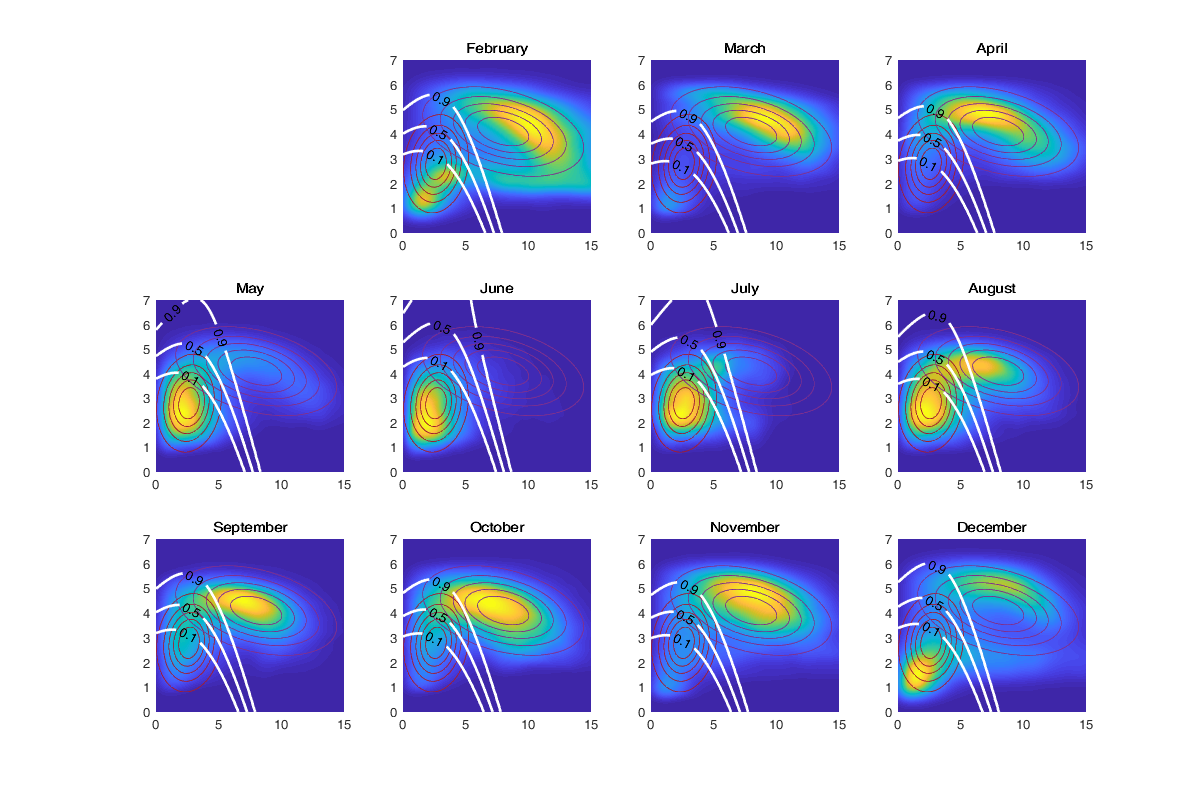

figure('position',[0 0 1200 800]); hold on; 
for i=2:batch
    id = dt(i)<t & dt(i+1)>t;
    subplot(3,4,i); hold on
    
%     surf(xi1, xi2, ftime(:,:,i))
%     contour3(xi1, xi2, ampli(i)*f_1,15,'Color',[162 29 49]/255)
%     contour3(xi1, xi2, (1-ampli(i))*f_2,15,'Color',[127 47 141]/255)
%     axis tight;shading interp; view(37,31)
%     title(month(median(dc(1).time(id)),'name'))
%     Ax = gca; Ax.XAxis.TickValues=[]; Ax.YAxis.TickValues=[]; Ax.ZAxis.TickValues=[];
    

    pcolor(xi1(1,:), xi2(:,1), ftime(:,:,i)./max(max(ftime(:,:,i))))
    contour(xi1, xi2, amplit(i)*f_1,5,'Color',[162 29 49]/255);
    contour(xi1, xi2, (1-amplit(i))*f_2,5,'Color',[127 47 141]/255);
    contour(xi1, xi2, (1-amplit(i))*f_2./(amplit(i)*f_1+(1-amplit(i))*f_2),[.1 .5 .9],'w','ShowText','on','LineWidth',2)
    axis tight;shading interp; title(month(median(dc(1).time(id)),'name'))
    %xlabel('airspeed [m/s]'); ylabel('\sigma_{vvp} [m/s]');
end

% [xData, yData] = prepareCurveData( dt(1:end-1)+diff(dt)/2, a1 );
% [fitresult, gof] = fit( xData, yData, fittype( 'sin3' ) );
% al = fitresult(t);
% figure; hold on;
% h = plot( fitresult, xData, yData );

## Over space

amplir = nan(1,numel(dc));
fradar = nan(size(xi1,1), size(xi1,2),numel(dc));
for i_d=1:numel(dc)-1
    X = [reshape(v_a(:,:,i_d),[],1),reshape(sdvvp(:,:,i_d),[],1)];
    X = X(~any(isnan(X),2),:);
    if ~isempty(X)
        fradar(:,:,i_d) = reshape(ksdensity(X, [xi1(:), xi2(:)]),size(xi1));
        fradar(:,:,i_d) = fradar(:,:,i_d)./sum(sum(fradar(:,:,i_d)));
        mismatch = @(alpha) ( alpha.*f_1 + (1-alpha).*f_2);
        amplir(i_d) = fminsearch(@(alpha) sum(sum((fradar(:,:,i_d)-mismatch(alpha)).^2)) , 0.5 ); 
    end
end
amplir(amplir==0)=nan;

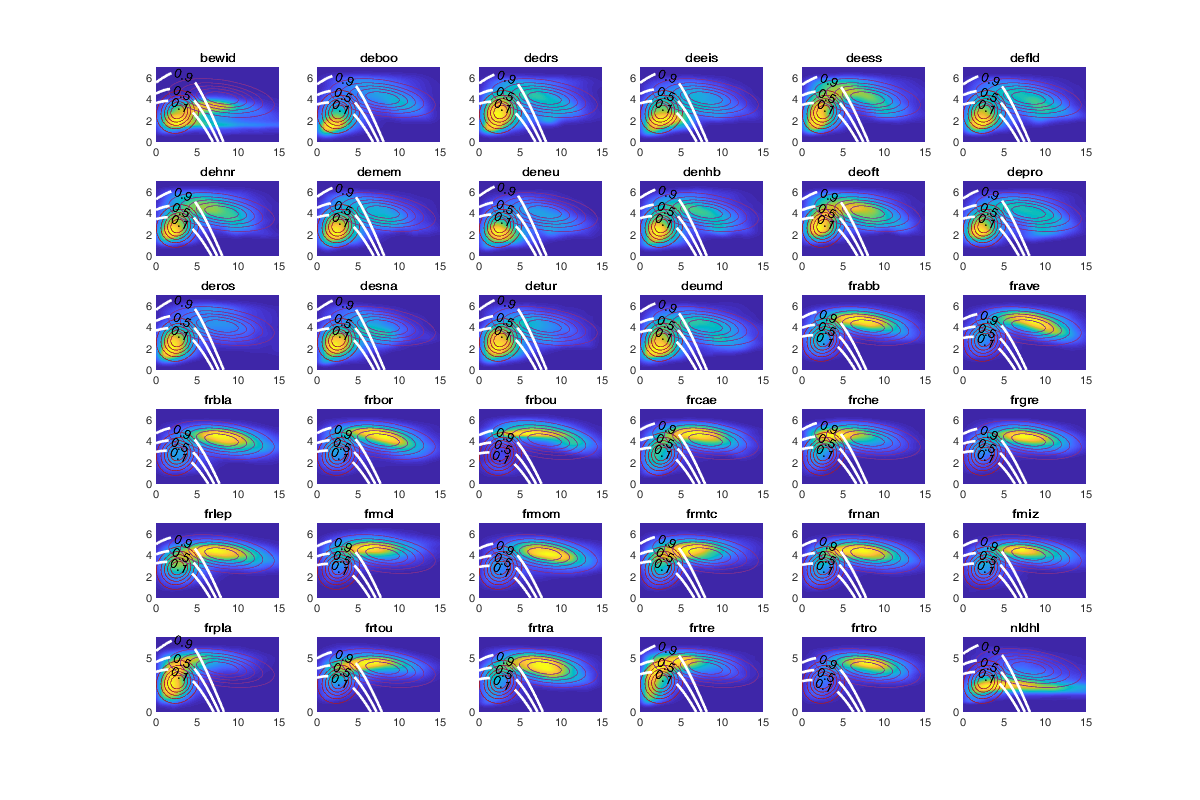

figure('position',[0 0 1200 800]); hold on; 
for i_d=1:numel(dc)-1
    subplot(6,6,i_d); hold on
    
%     surf(xi1, xi2, fradar(:,:,i_d))
%     contour3(xi1, xi2, amplir(i_d)*f_1,15,'Color',[162 29 49]/255)
%     contour3(xi1, xi2, (1-amplir(i_d))*f_2,15,'Color',[127 47 141]/255)
%     title(dc(i_d).name)
%     shading interp; view(37,31)
    
    pcolor(xi1(1,:), xi2(:,1), fradar(:,:,i_d)./max(max(fradar(:,:,i_d))))
    contour(xi1, xi2, amplir(i_d)*f_1,5,'Color',[162 29 49]/255);
    contour(xi1, xi2, (1-amplir(i_d))*f_2,5,'Color',[127 47 141]/255);
    contour(xi1, xi2, (1-amplir(i_d))*f_2./(amplir(i_d)*f_1+(1-amplir(i_d))*f_2),[.1 .5 .9],'w','ShowText','on','LineWidth',2)
    axis tight;shading interp; title(dc(i_d).name)
    %xlabel('airspeed [m/s]'); ylabel('\sigma_{vvp} [m/s]');
end

## Over altitude

amplia = nan(1,25);
falt = nan(size(xi1,1), size(xi1,2), 25);
for i=1:25
    X = [reshape(v_a(:,i,:),[],1),reshape(sdvvp(:,i,:),[],1)];
    X = X(~any(isnan(X),2),:);
    if ~isempty(X)
        falt(:,:,i) = reshape(ksdensity(X, [xi1(:), xi2(:)]),size(xi1));
        falt(:,:,i) = falt(:,:,i)./sum(sum(falt(:,:,i)));
        mismatch = @(alpha) ( alpha.*f_1 + (1-alpha).*f_2);
        amplia(i) = fminsearch(@(alpha) sum(sum((falt(:,:,i)-mismatch(alpha)).^2)) , 0.5 ); 
    end
end
amplia(amplia==0)=nan;

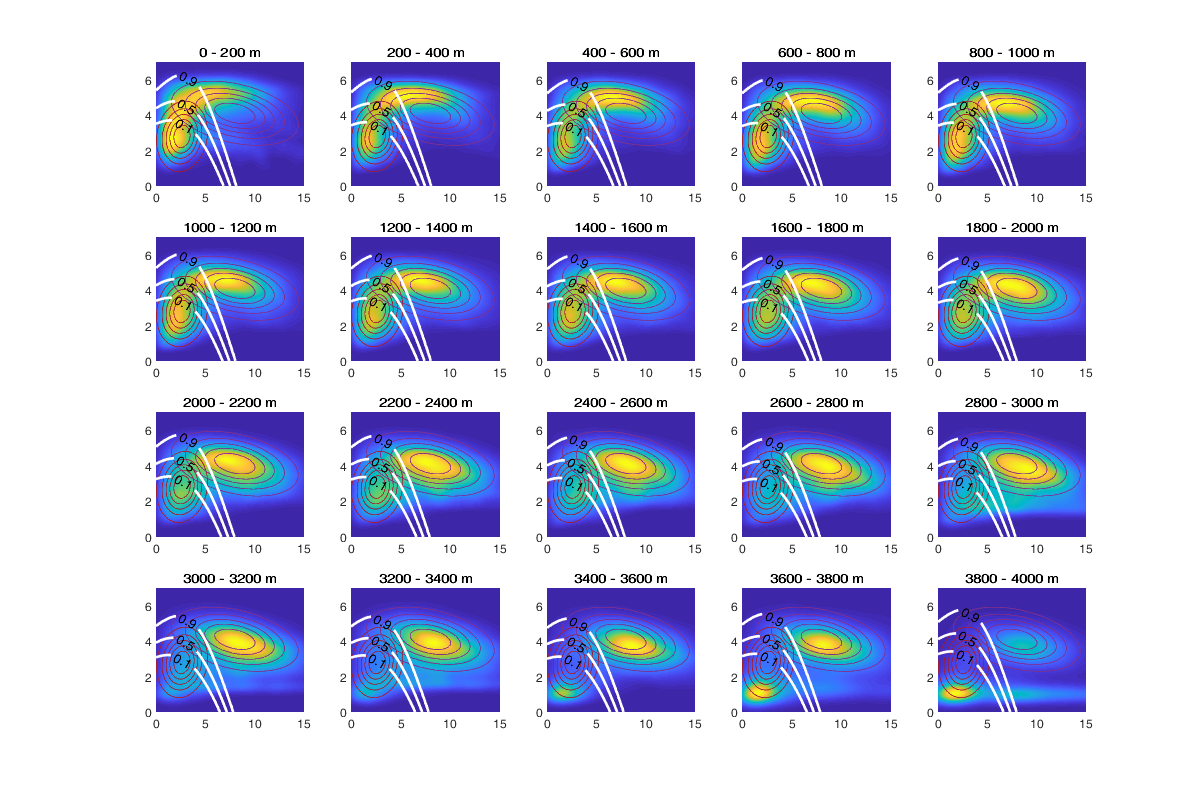

figure('position',[0 0 1200 800]); hold on; 
for i=1:20
    subplot(4,5,i); hold on
    
%     surf(xi1, xi2, falt(:,:,i))
%     contour3(xi1, xi2, amplia(i)*f_1,15,'Color',[162 29 49]/255)
%     contour3(xi1, xi2, (1-amplia(i))*f_2,15,'Color',[127 47 141]/255)
%     shading interp;  view(37,31)
    
    pcolor(xi1(1,:), xi2(:,1), falt(:,:,i)./max(max(falt(:,:,i))))
    contour(xi1, xi2, amplia(i)*f_1,5,'Color',[162 29 49]/255);
    contour(xi1, xi2, (1-amplia(i))*f_2,5,'Color',[127 47 141]/255);
    contour(xi1, xi2, (1-amplia(i))*f_2./(amplia(i)*f_1+(1-amplia(i))*f_2),[.1 .5 .9],'w','ShowText','on','LineWidth',2)
    axis tight;shading interp;
    %xlabel('airspeed [m/s]'); ylabel('\sigma_{vvp} [m/s]');
    title([num2str(dc(1).alt(i)-100) ' - ' num2str(dc(1).alt(i)+100) ' m'])
end

## Radar and month

ampliall = nan(batch,numel(dc));
fall = nan(size(xi1,1), size(xi1,2), batch, numel(dc));
for i=1:batch
    id = dt(i)<t & dt(i+1)>t;
    for i_d=1:numel(dc)
        X = [reshape(v_a(id,:,i_d),[],1),reshape(sdvvp(id,:,i_d),[],1)];
        X = X(~any(isnan(X),2),:);
        if ~isempty(X)
            fall(:,:,i,i_d) = reshape(ksdensity(X, [xi1(:), xi2(:)]),size(xi1));
            fall(:,:,i,i_d) = fall(:,:,i,i_d)./sum(sum(fall(:,:,i,i_d)));
            mismatch = @(alpha) ( alpha.*f_1 + (1-alpha).*f_2);
            ampliall(i,i_d) = fminbnd(@(alpha) sum(sum((fall(:,:,i,i_d)-mismatch(alpha)).^2)) , 0, 1 ); 
        end
    end
end
ampliall(ampliall==0)=nan;

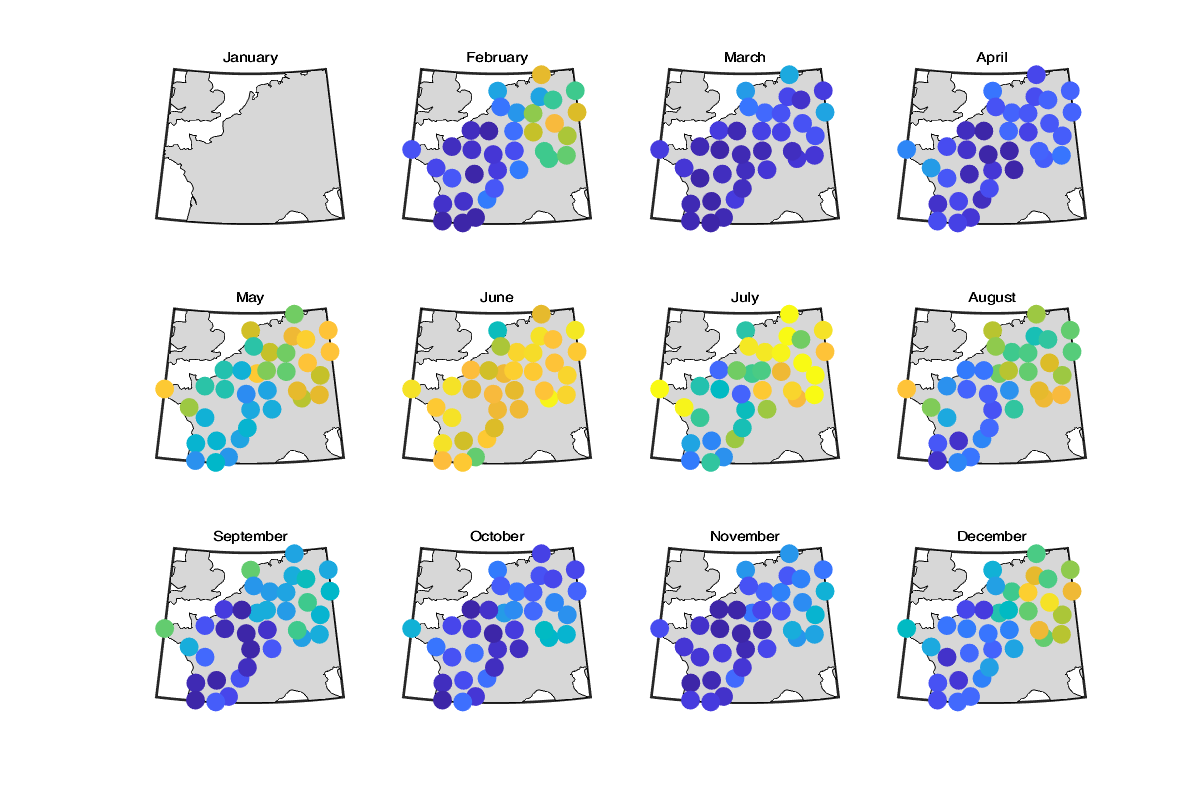

figure('position',[0 0 1200 800]);
for i=1:batch
    id = dt(i)<t & dt(i+1)>t;
    subplot(3,4,i);title(month(median(dc(1).time(id)),'name'))
    h = worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    geoshow( 'landareas.shp', 'FaceColor', [215 215 215]./255)
    scatterm([dc.lat], [dc.lon], 200, ampliall(i,:),'filled');
    caxis([0 1])
end

Fit over time for each radar. 

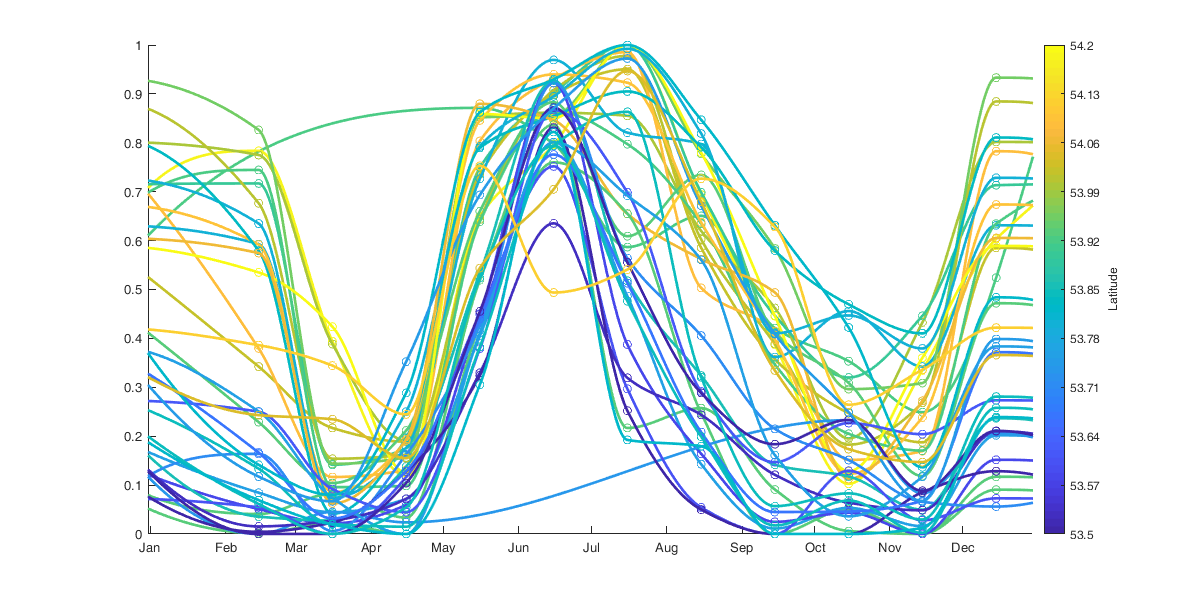

figure('position',[0 0 1200 600]); hold on;
warning('off')
c_map = parula;
ampliall(ampliall==0)=nan;
tmp = dt(1:end-1)+diff(dt)/2;
tmp = [tmp(end)-365 tmp 365+tmp(2)];
amplir= [ampliall(end,:); ampliall ;ampliall(2,:)];
for i_d=1:numel(dc)
    ti(:,i_d) = interp1( tmp, amplir(:,i_d),t, 'pchip');
%     [xData, yData] = prepareCurveData( dt(1:end-1)+diff(dt)/2, a(:,i_d) );
%     fitresult{i_d} = fit( xData, yData, fittype( 'sin2' ) );
    i_c = ceil((dc(i_d).lat-43.5)/(54.2-43.5)*64);
    % plot( xData, yData ,'o','Color',c_map(i_c,:));
    % plot( 1:365, fitresult{i_d}(1:365),'Color',c_map(i_c,:));
    plot( tmp, amplir(:,i_d) ,'o','Color',c_map(i_c,:));
    plot( t, ti(:,i_d),'Color',c_map(i_c,:),'LineWidth',2);
end
ylim([0 1]); xlim([0 365]); datetick('x','keeplimits');
c=colorbar;c.Label.String='Latitude';
c.TickLabels=string(linspace(53.5,54.2,11));

## Speed correction

How to correct for insect presence in the estimation of airspeed?

We can used the value fitted on the gaussians which informs us on the mean and std airspeed of insect and bird

Define airspeed range

as=0:0.1:25;

Compute the corresponding pdf for instect and bird

pdfI = normpdf(as,gmfit.mu(1,1), sqrt(gmfit.Sigma(1,1,1)));
pdfB = normpdf(as,gmfit.mu(2,1), sqrt(gmfit.Sigma(1,1,2)));

Compute the ratio of inset/bird. This corresponds to the relative a abundance of bird/insect present for such airspeed

alpha = pdfI./(pdfI+pdfB);

Plot the pdfs

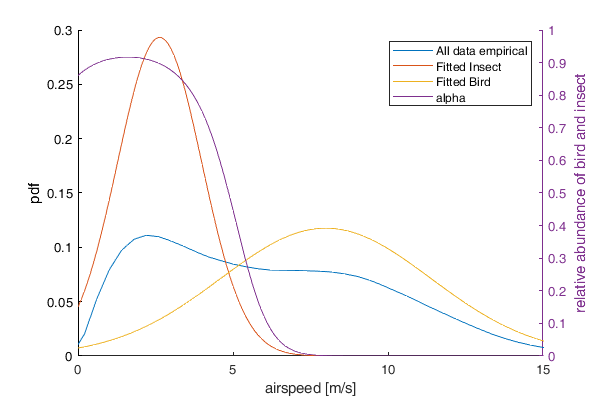

figure('position',[0 0 600 400]); hold on;
ksdensity(v_a(:))
plot(as,pdfI,'DisplayName','Fitted Insect');
plot(as,pdfB,'DisplayName','Fitted Bird');
%plot(as,pdfI.*gmfit.ComponentProportion(1)+pdfB.*gmfit.ComponentProportion(2),'DisplayName','Fitted Bird');
xlabel('airspeed [m/s]'); ylabel('pdf')
yyaxis right; ylabel('relative abundance of bird and insect')
plot(as,alpha,'DisplayName','alpha');
xlim([0 15])
l=legend(); l.String{1} ='All data empirical';

Build Correction function

speed_corr_0 = @(speed, insect) speed + insect .* diff(gmfit.mu(:,1));
speed_corr = @(speed, insect) speed .* (1 - insect + sqrt(gmfit.Sigma(1,1,2))/sqrt(gmfit.Sigma(1,1,1)).*insect) + (gmfit.mu(2,1) - gmfit.mu(1,1)*sqrt(gmfit.Sigma(1,1,2))/sqrt(gmfit.Sigma(1,1,1)) ).*insect;

Illustration of the correction function assuming the relative insection abundance follow the 1D seperation

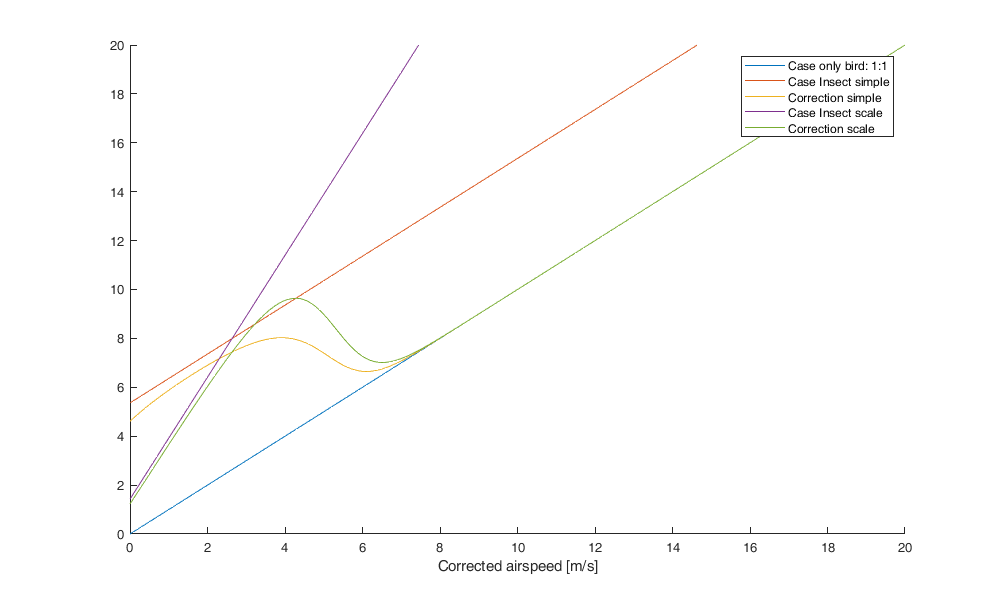

figure('position',[0 0 1000 600]); hold on;
plot(as,as,'DisplayName','Case only bird: 1:1')
plot(as,speed_corr_0(as,1),'DisplayName','Case Insect simple')
plot(as,speed_corr_0(as,alpha),'DisplayName','Correction simple')
plot(as,speed_corr(as,1),'DisplayName','Case Insect scale');
plot(as,speed_corr(as,alpha),'DisplayName','Correction scale');
xlabel('measured airspeed [m/s]')
xlabel('Corrected airspeed [m/s]')
ylim([0 20]); legend()

Test for synthetic case

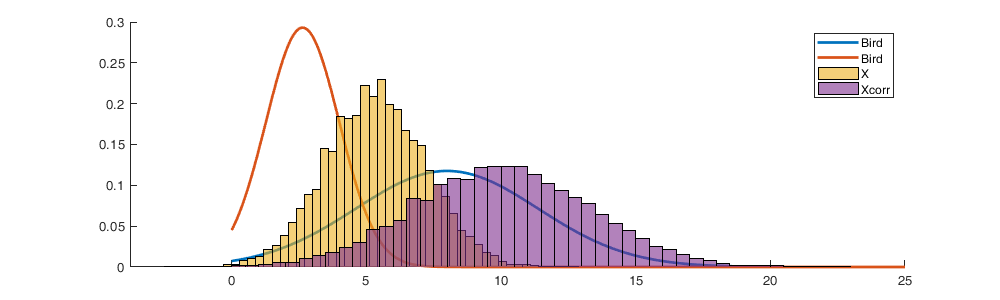

alpha0 = 0.5;

XI = normrnd(gmfit.mu(1,1), sqrt(gmfit.Sigma(1,1,1)),10000,1);
XB = normrnd(gmfit.mu(2,1), sqrt(gmfit.Sigma(1,1,2)),10000,1);
%XI = normrnd(gmfit.mu(1,1), 2.5,1000,1);
%XB = normrnd(gmfit.mu(2,1), 2.5,1000,1);
X = alpha0*XI + (1-alpha0)*XB;


Xcorr = X .* (1 - alpha0 + sqrt(gmfit.Sigma(1,1,2))/sqrt(gmfit.Sigma(1,1,1)).*alpha0) + (gmfit.mu(2,1) - gmfit.mu(1,1)*sqrt(gmfit.Sigma(1,1,2))/sqrt(gmfit.Sigma(1,1,1)) ).*alpha0;
%Xcorr = X*(1-alpha0+4.1/2.8*alpha0) + (8 - 2.6*4.1/2.8).*alpha0;

figure('position',[0 0 1000 300]); hold on;
plot(as,pdfB,'DisplayName','Bird','linewidth',2);
plot(as,pdfI,'DisplayName','Bird','linewidth',2);
histogram(X,'Normalization','pdf')
histogram(Xcorr,'Normalization','pdf')
legend()

## Apply filter

parfor i_d=1:numel(dc)

    % Compute insect proportion
    tmp1 = repmat(ti(:,i_d),1,25).*reshape(pdf(gm1,[reshape(v_adc,[],1) reshape(dc(i_d).sd_vvp2,[],1)]),size(v_adc));
    tmp2 = (1-repmat(ti(:,i_d),1,25)).*reshape(pdf(gm2,[reshape(v_adc,[],1) reshape(dc(i_d).sd_vvp2,[],1)]),size(v_adc));
    dc(i_d).insect = tmp1 ./(tmp1+tmp2);
    
    % Interpolate the insect/bird ratio when dens3 exist but not sd_vvp/u/v
    Finsect = scatteredInterpolant(X(~isnan(dc(i_d).insect)), Y(~isnan(dc(i_d).insect)), dc(i_d).insect(~isnan(dc(i_d).insect)),'linear','none');
    idp = ~(isnan(dc(i_d).dens3)) & isnan(dc(i_d).insect);
    dc(i_d).insect(idp) = Finsect(X(idp), Y(idp));
    dc(i_d).insect(dc(i_d).insect<0)=0;
    dc(i_d).insect(dc(i_d).insect>1)=1;
    % imagesc(dc(i_d).insect','AlphaData',~isnan(dc(i_d).insect'))
    
    % Correct density by removing the 1-ratio of insect
    dc(i_d).dens4 = dc(i_d).dens3 .* (1-dc(i_d).insect);
    
    % Compute airspeed component (after interpolation so can't use v_a)
    airspeed_u = dc(i_d).u-dc(i_d).windu;
    airspeed_v = dc(i_d).v-dc(i_d).windv;
    airspeed_l2 = sqrt(airspeed_u.^2 + airspeed_v.^2);

    % Compute the correction factor
    cc = speed_corr(airspeed_l2, dc(i_d).insect)
    
    % apply to each component
    dc(i_d).u2 = airspeed_u.*cc./airspeed_l2 + dc(i_d).windu;
    dc(i_d).v2 = airspeed_v.*cc./airspeed_l2 + dc(i_d).windv;
end

figure('position',[0 0 1000 300]); hold on;
ksdensity(reshape(sqrt( ([dc.u2] - [dc.windu]).^2 + ([dc.v2] - [dc.windv]).^2),1,[]))
ksdensity(reshape(sqrt( ([dc.u] - [dc.windu]).^2 + ([dc.v] - [dc.windv]).^2),1,[]))
xlabel('Air speed histogram')
legend('after correction','before correction')

## View result and save

CleaningV(dc)

Save

% save('data/dc_corr','dc','start_date','end_date','quantity','-v7.3')